# Inverse Kinematics Algorithm

## Modeling and Control of Robotic Manipulators

#### Code to switch between the different cases in the tasks

simulationmode='ROS';    % 1-9)

disp(['simulationmode : ' simulationmode]);

simulationmode : ROS


% mode='varJ';    % 3)
% mode='invKin';    % 5)
  mode='invKinDamped';  % 9)

disp(['inverse kinematics algorithm : ' mode]);

inverse kinematics algorithm : invKinDamped


#### UR10

robot = importrobot('ur10.urdf'); % 1)
eeframename = 'ee_link'; % name of end effector frame for forward kinematics
dof = 6; % degrees of freedom
K = 0.1*eye(6); % gain matrix     % 5+7)
lambdasqr = 0.05*eye(dof); % damping factor for inverse kinematics algorithm with damped least squares   % 9)


#### 1.  Load Reference Trajectory

Load the reference trajectory with `load 'TrajectoryUR10.mat'` and plot it with `plotTaskSpaceTrajectory`. 

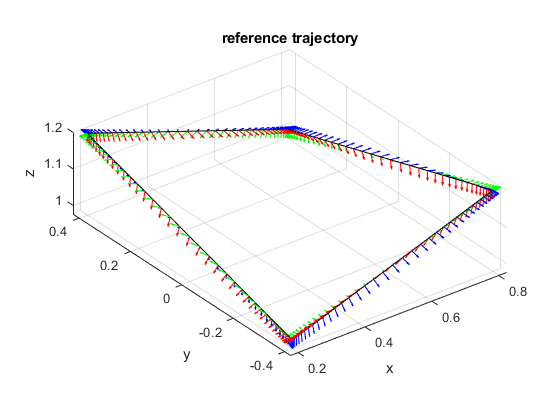

load TrajectoryUR10.mat;
figure(1);
plotTaskSpaceTrajectory(tformxd);
title('reference trajectory');

tformx = zeros(4,4,length(t)); % the robot's actual trajectory
poseerror = zeros(6,length(t));
q = zeros(dof,length(t));  % joint configuration
qdot = zeros(dof,length(t));  % joint velocities
qdotnull = zeros(dof,length(t));  % null space joint velocities
e = zeros(6,length(t));  % orientation and pose error
w = zeros(1,length(t)); % volume of manipulation ellipsoid
condJ = zeros(1,length(t)); % condition number of Jacobian

#### 2. Determine initial joint configuration

Determine the joint configuration *confq0* that corresponds to the initial reference pose *tformxd(:,:,1)* using the inverse kinematics solver `robotics.InverseKinematics` (see lab on Inverse Kinematics).

*confq0* determines the initial pose *q(:,1)* of the resolved rate motion control. The array *tformx(:,:,k)* retains the transforms of the actual end effector frame at time instances *k*.

% setup inverse kinematics solver
ik = robotics.InverseKinematics('RigidBodyTree', robot);
% Disable random restart to ensure consistent IK solutions
ik.SolverParameters.AllowRandomRestart = false;
% Specify weights for the tolerances on each component of the goal pose.
weights = ones(6,1);
% determine initial joint configuration from inverse kinematics solver
initialguess = JointVec2JointConf(robot,[0 0 0 -pi/2 0 0]); % better than homeConfiguration
confq0 = ik(eeframename, tformxd(:,:,1), weights, initialguess);

% map angle to interval [-pi, pi]
q(:,1) = wrapToPi(JointConf2JointVec(confq0));
confq0 = JointVec2JointConf(robot,q(:,1));

disp(['initial joint configuration:' mat2str(q(:,1)',3)]);

initial joint configuration:[-1.28 -1.06 2.33 -1.27 -2.85 1.06e-08]


tformx(:,:,1) = robot.getTransform(confq0, eeframename);

% check for feasibility of initial pose
if (norm(tformxd(:,:,1)-tformx(:,:,1)) > 1e-2)
    disp(['initial configuration infeasible']);
    disp(['target pose: ' mat2str(tformxd(:,:,1))]);
    disp(['inverse kinematics solution : ' mat2str(tformx(:,:,1))]);
    disp(['error norm : ' num2str(norm(tformxd(:,:,1)-tformx(:,:,1)))]);
    return;
end


### Code for the tasks 3, 4, 5 and 9

Add your solution for assignement 3, 4, 5 and 9 in the given code structure

% mode openloop with constant or varying Jacobian, or inverse
% kinematic control scheme

% error_calc = zeros(6,length(t));
if isequal(simulationmode,'Matlab')
    for k=1:length(t)-1
    
        % calculate generalized pose error  % 4)        
        e(:,k)=robotics.manip.internal.IKHelpers.poseError(tformxd(:,:,k), tformx(:,:,k));
        
%         eo = tform2trvec(tformxd(:,:,k)) - tform2trvec(tformx(:,:,k));
%         quat1 = quaternion(tform2quat(tformx(:,:,k)));
%         quat2 = quaternion(tform2quat(tformxd(:,:,k)));
%         c = compact(quat2*conj(quat1));
%         ep = c(2:4);
%         error_calc(:,k) = [eo'; ep'];
        
        % calculate geometric Jacobian (due to angle-axis/quaternion representation)
        J = robot.geometricJacobian(JointVec2JointConf(robot,q(:,k)),eeframename);
        condJ(k) = cond(J); % calculate condition number ratio lambda_n/lambda_1
    
    switch mode
        
        case 'varJ' % 3)
                        % Open-loop control with varying jacobian (w.r.t. current configuration q)
                        % resolved rate motion control with J(q_k)
                        qdot(:,k) = J\xdotd(:,k);
                
        case 'invKin'   % 5)
            %             % Feedback control with inverse kinematics algorithm
            %             % poseerror [wx wy wz ex ey ez]
            %             % pose error orientation part from quaternion
            %             % equation (3.91) Siciliano
            %             % inverse kinematic control law dotq = J^(-1)(q)(dot xd + K e)
                        qdot(:,k) = J\(xdotd(:,k) + K*e(:,k));
            
            
        case 'invKinDamped' % 9)
            %             % Feedback control with inverse kinematics algorithm with damping term
            %             % inverse kinematic control law dotq = (J^T J + lambda^2 I)^(-1)(J^T(dot xd + K e))
                        qdot(:,k)=(J'*J + lambdasqr)\(J'*(xdotd(:,k) + K*e(:,k)));
            
    end
        q(:,k+1) = q(:,k) + qdot(:,k)*deltat; % simple integrator
        tformx(:,:,k+1)=robot.getTransform(JointVec2JointConf(robot,q(:,k+1)),eeframename);
    end    
     
    e(:,end) = robotics.manip.internal.IKHelpers.poseError(tformxd(:,:,end), tformx(:,:,end));

%         eo = tform2trvec(tformxd(:,:,end)) - tform2trvec(tformx(:,:,end));
%         quat1 = quaternion(tform2quat(tformx(:,:,end)));
%         quat2 = quaternion(tform2quat(tformxd(:,:,end)));
%         c = compact(quat2*conj(quat1));
%         ep = c(2:4);
%         error_calc(:,end) = [eo'; ep'];
    
end

#### 3. Differential Kinematics

Reuse the code for resolved rate motion control of the lab on Differential Kinematics based on the difference equation 


$$\mathbf{q}_{k+1} = \mathbf{q}_{k} + \mathbf{J}(\mathbf{q_k})^{-1} \dot{\mathbf{x}}_k \Delta t $$


for the same constant velocity motion to track the reference trajectory in open loop mode ($$t \in [0, 8]$$ seconds). The vector of reference velocities  $$\dot{\mathbf{x}}_k$$ is provided in the array *xdotd(:,k)*.  The loop iterates through the sequence of time stamps to calculate the joint velocity *dotq(:,k)* according to the inverse kinematic control laws and then integrates the joint states from *q(:,k)* to *q(:,k+1)*.

#### 4. Calculate the pose error

Augment the code to implement the inverse kinematic control with quaternion error.

For each iteration:

Calculate the position error $$\mathbf{e}_p$$ between reference frame and current robot frame with help of `getTransform` and `tform2trvec`. Calculate the quaternions of reference frame $$ \mathcal{Q}_d$$ and end effector frame  $$\mathcal{Q}_e$$  with help of `getTransform` and `tform2quat`. Caluclate the orientation error $$\mathbf{e}_o$$ either according to Eq. (25) using ordinary vector operations or directly by  Eq. (24) utilizing the quaternion class with methods `inverse `and `vector` to extract the vector part of quaternion $$\Delta \mathcal{Q}$$.


$$\dot{\mathbf{e}} =\left\lbrack \begin{array}{c}
{\dot{\mathbf{e}} }_o \\
{\dot{\mathbf{e}} }_p 
\end{array}\right\rbrack$$


(Notice, that for Jacobians in ROS and the Robotics system toolbox the total error defines position and orientation error in reverse order.)

#### 5. Inverse Kinematic Control

Implement the control law for inverse kinematic control with quaternion error according to (26)


$$\dot{\mathbf{q}_{k}} = \mathbf{J}(\mathbf{q_k})^{-1} ( \dot{\mathbf{x}}_{d_k} + \mathbf{K} \mathbf{e}_k )
$$


Use a 6-by-6 identity gain matrix $$\mathbf{K}=\mathbf{I}$$. Notice, that you can use the left array division operator `\`  to solve


$$\mathbf{J}(\mathbf{q_k}) \dot{\mathbf{q}_{k}} =  ( \dot{\mathbf{x}}_{d_k} + \mathbf{K} \mathbf{e}_k )
$$


rather than to explicitly calculate the inverse Jacobian $$\mathbf{J}(\mathbf{q_k})^{-1}$$.

#### 6. Plot the motion

Simulate the UR10 robot motion under inverse kinematic control with an Euler integration step $$\mathbf{q}_{k+1}= \mathbf{q}_{k} + 
\dot{\mathbf{q}}_{k} \Delta t$ 
$ and plot the reference motion for position and orientation (quaternion), the actual motion of position and orientation (quaternion) and position error $$\mathbf{e}_p$$ and quaternion orientation error $$\mathbf{e}_o$$ over time

as shown in Figure 3. Compare the errors with the open-loop resolved rate motion control law


$$\mathbf{J}(\mathbf{q_k}) \dot{\mathbf{q}_{k}} =  
\dot{\mathbf{x}}_{d_k} 
$$


(see assignment Differential Kinematics).

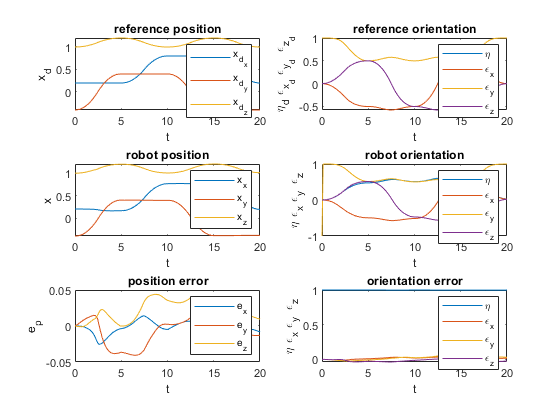

    figure(2);
    plotTaskSpaceError(t,tformx,tformxd);

    disp(['final position error=' num2str(norm(e(1:3,end-1)),2)]);

final position error=0.085


    disp(['final orientation error=' num2str(norm(e(4:6,end-1)),2)]);

final orientation error=0.018


#### 7. Report the position and orientation errors

Multiply the gain matrix  *K* by scalars $$\{0.1 , \ 1 ,\ 10 \}$$ and report the average (`mean`)  across the entire motion of position errors $$\mathbf{e}_p$$ and orientation errors $$\mathbf{e}_o$$ . Complete the table in the pdf-filefor the gains (K=0.1; K=1.0 and K=10.0).

    disp(['average position error=' num2str(norm(mean(e(1:3,:),2)),2)]);

average position error=0.031


    disp(['average orientation error=' num2str(norm(mean(e(4:6,:),2)),2)]);

average orientation error=0.027


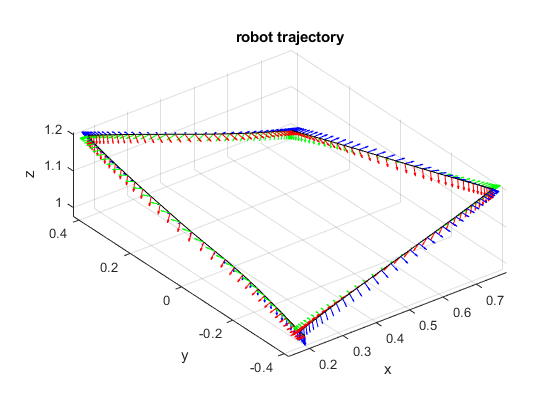

    figure(3);
    plotTaskSpaceTrajectory(tformx);
    title('robot trajectory');

#### 8. Plot the joint velocities

Plot the vector of joint space velocities $$\dot{\mathbf{q}}$$ across the motion as shown in Figure 4 and report the maximum  (`max`) absolute joint velocities. Notice, that the reference trajectory along the first segment gets close to a singularity resulting in excessive joint velocities. Plot the condition number (`cond`) of the geometric Jacobian across the motion and observe the singularity.

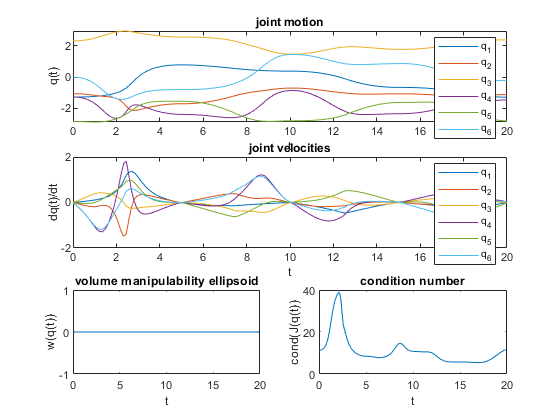

    figure(4);
    plotJointMotion(t,q,qdot,mode,w,condJ,qdotnull);

    
    disp(['maximum absolute joint velocities= ' mat2str(max(abs(qdot),[],2)',2)]);

maximum absolute joint velocities= [1.4 1.5 0.43 1.8 0.98 1.2]


    disp(['minimum manipulability ellipsoid volume=' num2str(norm(min(w)),2)]);

minimum manipulability ellipsoid volume=0


    disp(['maximum condition number J=' num2str(norm(max(condJ)),3)]);

maximum condition number J=38.9


#### 9. Damped Inverse Kinematic Algorithm

Modify the control law to the damped inverse kinematics algorithm according to Eq. (15) with $$\lambda=0.05$$. Compare the average pose error and maximum joint velocities with the non-damped inverse kinematics algorithm.

#### 10.  Connect with ROS

**optional:** Simulate the UR10 motion under inverse kinematic control algorithm with the Gazebo simulator. Notice, this tasks requires a computer that is able to run the ROS Gazebo simulator and that the ROS packages for the UR10, Gazebo and ROS Control are installed. Launch the Gazebo simulation of the UR10 robot arm with the joint effort interface in Ubuntu ROS. 

         `roslaunch ur_launch ur10_sim_gazebo.launch`

#### 11. Switch controller

**optional: **To switch from position controller to velocity controller send a switch service command on the following topic:

`rosservice call /ur10/controller_manager/switch_controller "start_controllers:`

`- ['joint0_velocity_controller','joint1_velocity_controller','joint2_velocity_controller','joint3_velocity_controller','joint4_velocity_controller','joint5_velocity_controller']`

`stop_controllers:`

`- ['vel_based_pos_traj_controller']`

`strictness: 1"`

This assignment employs the joint velocity controller that subscribes to velocity commands. After launching the Gazebo simulator verify that the ROS master provides topics

`/ur10/joint_states/` and `/ur10/joint0/velocity_controller/command, `with `rostopic list`

#### 12.  Simulate with ROS

**optional:** Notice, that the velocity command requires a separate publisher and topic for each robot joint enumerated from $$0$$ to $$5$$, from first to sixth joint. The following code generates publishers for the velocity commands and subscribers for the joint state topic.

if isequal(simulationmode,'ROS')
    
    if isempty(getenv('ROS_MASTER_URI'))
        rosinit('http://ubuntu:11311/')
    end
    
    % publisher for joint velocity commands, one publisher per joint
    for jointCount=1:dof
        [jointVelPubJoint(jointCount), jtMsg] = rospublisher(['/ur10/joint' num2str(jointCount-1) '_velocity_controller/command']);
    end
    
    % subscriber for joint states
    jointStateSub = rossubscriber('/ur10/joint_states');
end

Initializing global node /matlab_global_node_69217 with NodeURI http://192.168.2.108:53463/


#### 13. Service Request Message

**optional: **This code configures the Gazebo simulator such that the initial Sawyer joint configuration coincides with the joint configuration *confq0* of the start pose of the reference trajectory. The command `call(serviceclient,requestmsg)` sends the service request message *requestmsg* to the service *serviceclient*.

       % configure Gazebo for initial joint configuation confq0
    mdlConfigClient = rossvcclient('gazebo/set_model_configuration');
    
    % Compose the required service message. It includes the joint names
    % and corresponding joint positions to send to Gazebo. Call the service using this message.
    msg = rosmessage(mdlConfigClient);
    msg.ModelName = 'ur10';
    msg.UrdfParamName = 'robot_description';
    for i=1:dof
        msg.JointNames(i)=cellstr(confq0(i).JointName);
        msg.JointPositions(i)=confq0(i).JointPosition;
    end
    
    call(mdlConfigClient, msg);

#### 14. Visualize in in ROS

**optional:** Visualize the arm motion in ROS with RVIZ. Reutilizethe code for visualization in real time from the assignment on Forward Kinematics.

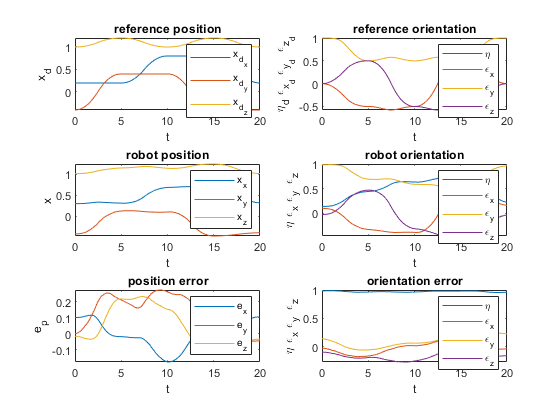

    rateObj=robotics.Rate(length(t)/tfinal);  % create rate object : desired rate in Hz (alternative to using rostime)
    
    for i=1:length(t)
        
        % receive joint state from simulation
        jsMsg = receive(jointStateSub);
        
        % Reorder joint values
        q(1,i) = double(jsMsg.Position(3));
        q(2,i) = double(jsMsg.Position(2));
        q(3,i) = double(jsMsg.Position(1));
        q(4,i) = double(jsMsg.Position(4));
        q(5,i) = double(jsMsg.Position(5));
        q(6,i) = double(jsMsg.Position(6));
        
        % Find the corresponding index k in tformxd vector for joint
        % state time stamp t.
        h = ceil((rateObj.TotalElapsedTime + 1e-8)/deltat);
        if h>length(t)
            break
        end
        
        % Log task pose data.
        tformx(:,:,i) = robot.getTransform(JointVec2JointConf(robot,q(:,i)),eeframename);
        
        % generalized pose error (position and quaternion orientation error)        
        e(:,i)=robotics.manip.internal.IKHelpers.poseError(tformxd(:,:,h),tformx(:,:,i));
        
        % calculate geometric Jacobian
        J=robot.geometricJacobian(JointVec2JointConf(robot,q(:,i)),eeframename);
        
        condJ(i)=cond(J); % calculate condition number ratio lambda_n/lambda_1
        
        switch mode
            case 'varJ'
                qdot(:,i)=J\xdotd(:,h); %h
            case 'invKin'
                % inverse kinematic control law dotq = J^(-1)(q)(dot xd + K e)
                qdot(:,i)=J\(xdotd(:,h) + K*e(:,i));
            case 'invKinDamped'
                % inverse kinematic control law dotq = (J^T J + lambda^2 I)^(-1)(J^T(dot xd + K e))                
                qdot(:,i)=(J'*J + lambdasqr)\(J'*(xdotd(:,h) + K*e(:,i)));
        end
        
        % publish joint velocities
        for jointCount=1:dof
            jtMsg.Data = qdot(jointCount,i);
            send(jointVelPubJoint(jointCount), jtMsg);
        end
        
        waitfor(rateObj);
    end
    
    % stop robot motion
    for jointCount=1:dof
        jtMsg.Data = 0;
        send(jointVelPubJoint(jointCount), jtMsg);
    end
    
    figure(2);
    plotTaskSpaceError(t,tformx,tformxd);

    
    disp(['average position error=' num2str(norm(mean(e(4:6,:),2)),2)]);

average position error=0.17


    disp(['average orientation error=' num2str(norm(mean(e(1:3,:),2)),2)]);

average orientation error=0.08


    disp(['final position error=' num2str(norm(e(4:6,end-1)),2)]);

final position error=0.12


    disp(['final orientation error=' num2str(norm(e(1:3,end-1)),2)]);

final orientation error=0.57


    disp(['maximum absolute joint velocities= ' mat2str(max(abs(qdot),[],2)',2)]);

maximum absolute joint velocities= [0.53 0.4 0.27 0.43 0.52 0.58]


    disp(['minimum manipulability ellipsoid volume=' num2str(norm(min(w)),2)]);

minimum manipulability ellipsoid volume=0


    disp(['maximum condition number J=' num2str(norm(max(condJ)),3)]);

maximum condition number J=12.2


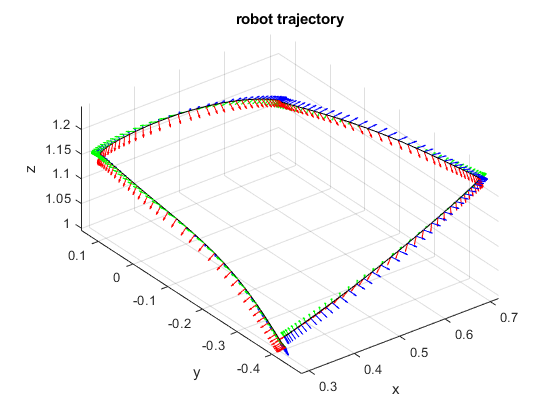

    
    figure(3);
    plotTaskSpaceTrajectory(tformx);
    title('robot trajectory');

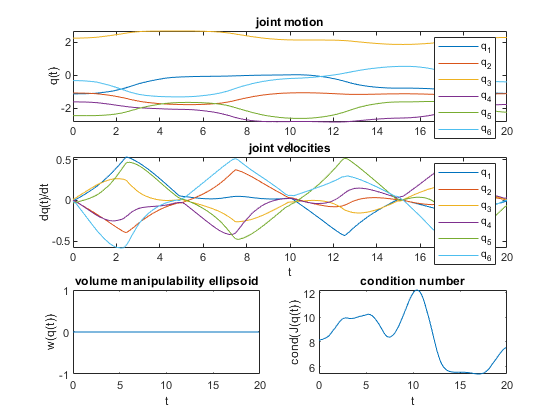

    
    figure(4);
    plotJointMotion(t,q,qdot,mode,w,condJ,qdotnull);

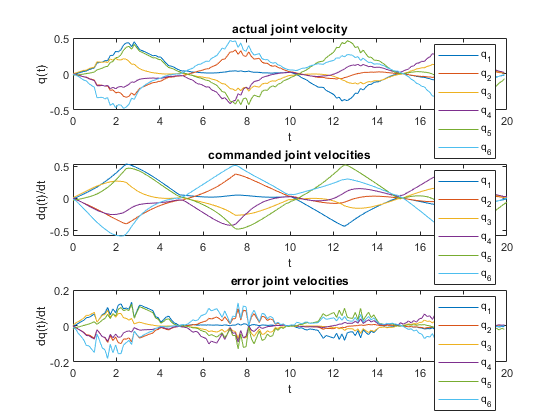

    
    figure(5);
    plotJointMotionTracking(t,q,qdot);